% plot_CL_with_AoA_all_relegend.m
% Reads sheets, creates subplots (one per sheet) and a combined plot of all Reynolds numbers.
filename = 'C:\Users\marke\Desktop\university\semester 8\Thesis\experiment\all series (Repaired).xlsx';
sheets = {'V=15','V=20','V=25','V=30','V=35'};
[folder, ~, ~] = fileparts(filename);

% Reynolds numbers corresponding to the sheets (must match order)
Re_vals = [150e3, 200e3, 250e3, 300e3, 350e3];
Re_labels = "Re = " + string(Re_vals);   % string array for legend/title

% initialize
n = numel(sheets);
allData = cell(1, n);

% Read sheets and store valid data
for k = 1:n
    sheet = sheets{k};
    fprintf('Reading sheet: %s\n', sheet);
    try
        T = readtable(filename, 'Sheet', sheet);
    catch ME
        fprintf('  Cannot read sheet %s: %s\n', sheet, ME.message);
        continue
    end

    if ~all(ismember({'AoA','CL'}, T.Properties.VariableNames))
        fprintf('  Sheet %s missing AoA or CL\n', sheet);
        continue
    end

    x = double(T.AoA);
    y = double(T.CL);
    valid = ~isnan(x) & ~isnan(y);
    x = x(valid); y = y(valid);
    if isempty(x)
        fprintf('  No valid (non-NaN) data in sheet %s\n', sheet);
        continue
    end

    % store with associated Reynolds label
    allData{k} = struct('sheet', sheet, 'AoA', x, 'CL', y, 'ReLabel', Re_labels(k));
    fprintf('  Stored %d points for %s\n', numel(x), sheet);
end

Reading sheet: V=15


  Stored 14 points for V=15


Reading sheet: V=20


  Stored 14 points for V=20


Reading sheet: V=25


  Stored 14 points for V=25


Reading sheet: V=30


  Stored 14 points for V=30


Reading sheet: V=35


  Stored 14 points for V=35



% Verify there is data
hasData = ~cellfun(@isempty, allData);
if ~any(hasData)
    error('No valid data found in any sheet. Check sheet names, column names, and NaNs.');
end

% Create subplots for individual sheets
numPlots = sum(hasData);
ncols = ceil(sqrt(numPlots));
nrows = ceil(numPlots / ncols);

fhSub = figure('Name','Per-Sheet Subplots','NumberTitle','off');
plotIdx = 0;
for k = 1:n
    s = allData{k};
    if isempty(s), continue; end
    plotIdx = plotIdx + 1;
    ax = subplot(nrows, ncols, plotIdx);
    plot(ax, s.AoA, s.CL, '-o', 'LineWidth', 1.2, 'MarkerSize', 6);
    grid(ax, 'on');
    xlabel(ax, 'AoA (deg)');
    ylabel(ax, 'C_L');
    title(ax, sprintf('%s — %s', s.sheet, s.ReLabel), 'Interpreter', 'none');

    % mark max CL
    [ymax, idx] = max(s.CL);
    xmax = s.AoA(idx);
    hold(ax, 'on');
    plot(ax, xmax, ymax, 'r*', 'MarkerSize', 10);
    text(ax, xmax, ymax, sprintf('  (%.2f, %.3f)', xmax, ymax), ...
        'VerticalAlignment', 'bottom', 'Color', 'r', 'FontWeight', 'bold');
    hold(ax, 'off');

    fprintf('Plot %s: AoA range [%.2f, %.2f], CL range [%.4f, %.4f]\n', ...
        s.sheet, min(s.AoA), max(s.AoA), min(s.CL), max(s.CL));
end

Plot V=15: AoA range [-4.20, 16.00], CL range [-0.5290, 0.9781]
Plot V=20: AoA range [-4.20, 16.00], CL range [-0.6011, 1.1315]
Plot V=25: AoA range [-4.20, 16.00], CL range [-0.6684, 1.2105]
Plot V=30: AoA range [-4.20, 16.00], CL range [-0.6930, 1.2264]
Plot V=35: AoA range [-4.20, 16.00], CL range [-0.6895, 1.2393]


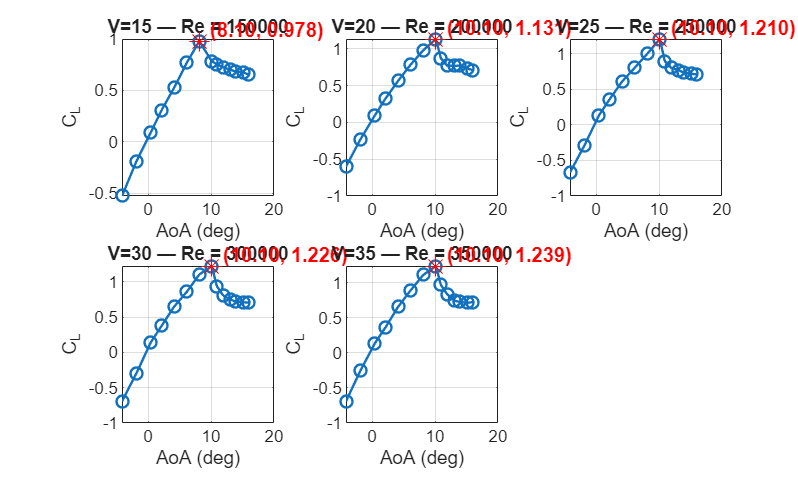


% optional super title
if exist('sgtitle','builtin')
    sgtitle('C_L vs AoA — Individual Velocities (Re shown)');
end

% save subplot figure
outSub = fullfile(folder, 'CL_vs_AoA_Subplots.png');
try
    exportgraphics(fhSub, outSub);
catch
    saveas(fhSub, outSub);
end

fprintf('Saved subplot figure: %s\n', outSub);

Saved subplot figure: C:\Users\marke\Desktop\university\semester 8\Thesis\experiment\CL_vs_AoA_Subplots.png


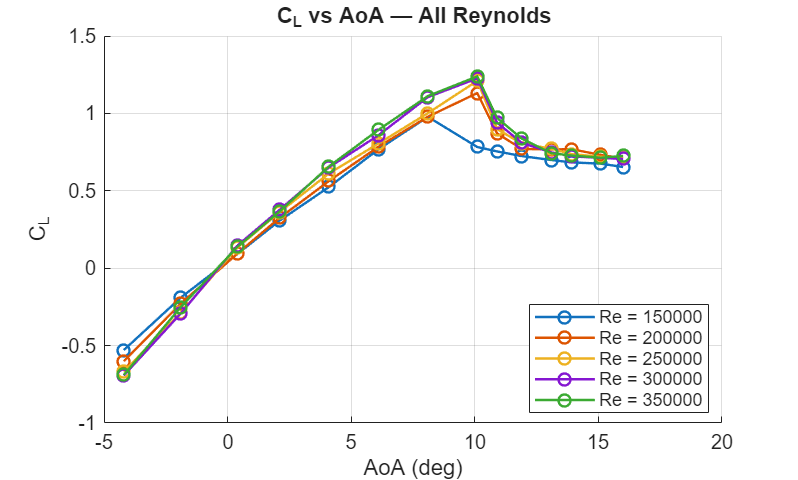


% Combined plot: all Reynolds (separate figure)
fhAll = figure('Name','All Reynolds','NumberTitle','off');
hold on; grid on;
leg = string.empty;
for k = 1:numel(allData)
    s = allData{k};
    if isempty(s) || isempty(s.AoA), continue; end
    plot(s.AoA, s.CL, '-o', 'LineWidth', 1.2, 'MarkerSize', 6);
    leg(end+1) = s.ReLabel; %#ok<SAGROW>
end
xlabel('AoA (deg)');
ylabel('C_L');
title('C_L vs AoA — All Reynolds');
legend(leg, 'Location', 'best');
hold off;

% Save combined figure
outAll = fullfile(folder, 'C_L_vs_AoA_All_Reynolds.png');
try
    exportgraphics(fhAll, outAll);
catch
    saveas(fhAll, outAll);
end

fprintf('Saved combined figure: %s\n', outAll);

Saved combined figure: C:\Users\marke\Desktop\university\semester 8\Thesis\experiment\C_L_vs_AoA_All_Reynolds.png
